# Results of the ex-vivo parametrics study

The objective of this study is to establish quantifiable parameters for assessing the roughness of bone endostium. Existing literature suggests that surface roughness can be effectively quantified by evaluating the **root mean square of height** relative to a planar surface, along with the **correlation length of height**, which provides insights into the horizontal dimension of surface irregularities. However, these parameters have not been characterized within the context of bone.

Consequently, our initial step involves conducting an analysis of bone imagery acquired via X-ray to discern and define these parameters specific to bone morphology.

## Introduction to the notion of waviness

The concepts such as waviness, roughness, and form are central in the study of a surface roughness. By examining the spatial frequency spectrum of a profile, we can discern the distinct  contributions of various components characterized by different frequencies, as illustrated in the following figure.

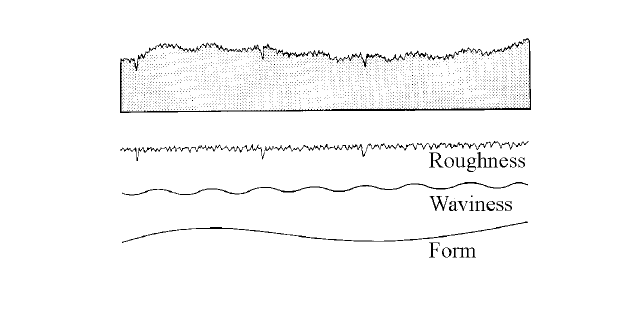

imageData = imread('The-measured-profile-is-the-addition-of-roughness-waviness-and-form.png');
imshow(imageData);

## Analysis of ex-vivo bones

The images where acquired on several ex-vivo bones with various profiles. The endost was extraxted using the `ExtractBoundary.m` function on a binarize image. The resolution of the X-Ray image is $9\mu m$.  

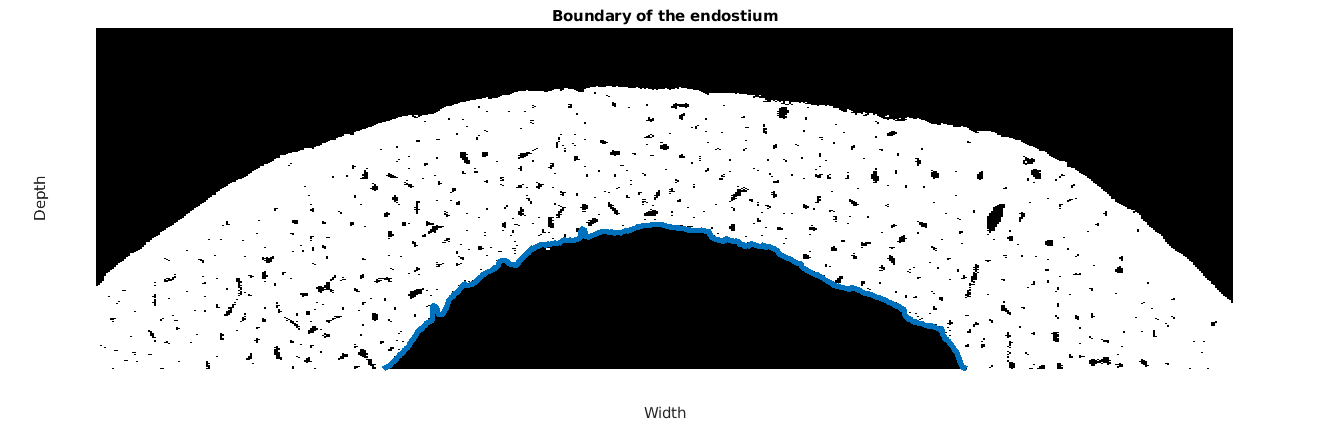

openfig("BoundaryEndost.fig");

### Cut off frequency determination 

In order to extract the rougness and both the waviness and the roughness components of the profile, we need to determine the cutt off frequency of the highpass filter. The usual cut off frequency to obtain *only the roughness* is a frequency that corresponds to a pattern of $0\ldotp 8\mathrm{mm}$ thus a frequency $f_{\mathrm{industry}} =1\ldotp 25\;\mathrm{mm⁻¹}$, in the industry. 

In order to obtain the corresponding values for the bone. We computed the mean height of the profile for various cut off frequency. When the mean heigth is equal to zero, we can consider that the parabolic form of the bone as been filtred, we therefore have the *roughness and the waviness* components. 

In order to give significance to our reults, we ploted the mean heigth regarding the frequency that corresponds to the wavelength in the bone, considering a velocity of $c=3500m\ldotp \mathrm{s⁻¹}$ and a temporale frequency $f_{\mathrm{temporal}} =2,5\mathrm{Mhz}$: 


$$f_{\lambda } =\frac{1}{\lambda }=\frac{1}{c/f_{\mathrm{temporal}} }\approx 0\ldotp 741\;\mathrm{mm⁻¹}$$


The results allow us to see that the frequency that allow to extract the waviness *and* the roughness, which corresponds to the blue line, is $\frac{f_{\lambda } }{10}\approx 0\ldotp 0741\;\mathrm{mm⁻¹}$. The frequency that allow to extract only the roughness, according the the industry is plotted in blue. 

We will know refer to the combination of roughness and waviness as waviness.

openfig("CuttOffFreq.fig");

### Root mean square of the extracted profile

The profile was filtred using the `highpass` function with the frequencies of interest. 

openfig("FiltredProfile.fig");

We can clearely distinguish from the original profile, the waviness and the roughness. The root mean square of these extracted profiles have distinct root mean square value. The roughness profile as a RMS of ${\mathrm{RMS}}_{\mathrm{waviness}} \approx 214\mu m$and ${\mathrm{RMS}}_{\mathrm{roughness}} \approx 33\mu m$. 

### Validation on other bones

These values have been validated on other image of the same bone and on other bones.

## Simulation on waviness and roughness of ex-vivo bones

In order to observe the interaction of the ultrasounds regarding the two type of extracted profile. We did a `SimSonic` simulation with the bone/soft tissu interface being both the roughness and waviness profiles. The original curved profile measured $15\mathrm{mm}$. We therefore did a extention of the waviness and roughness to recover the original length of the endosteium and a symmetry in order to reach a geometry of $30\mathrm{mm}$ of width. 

The 